generic genetic algo

knapsack

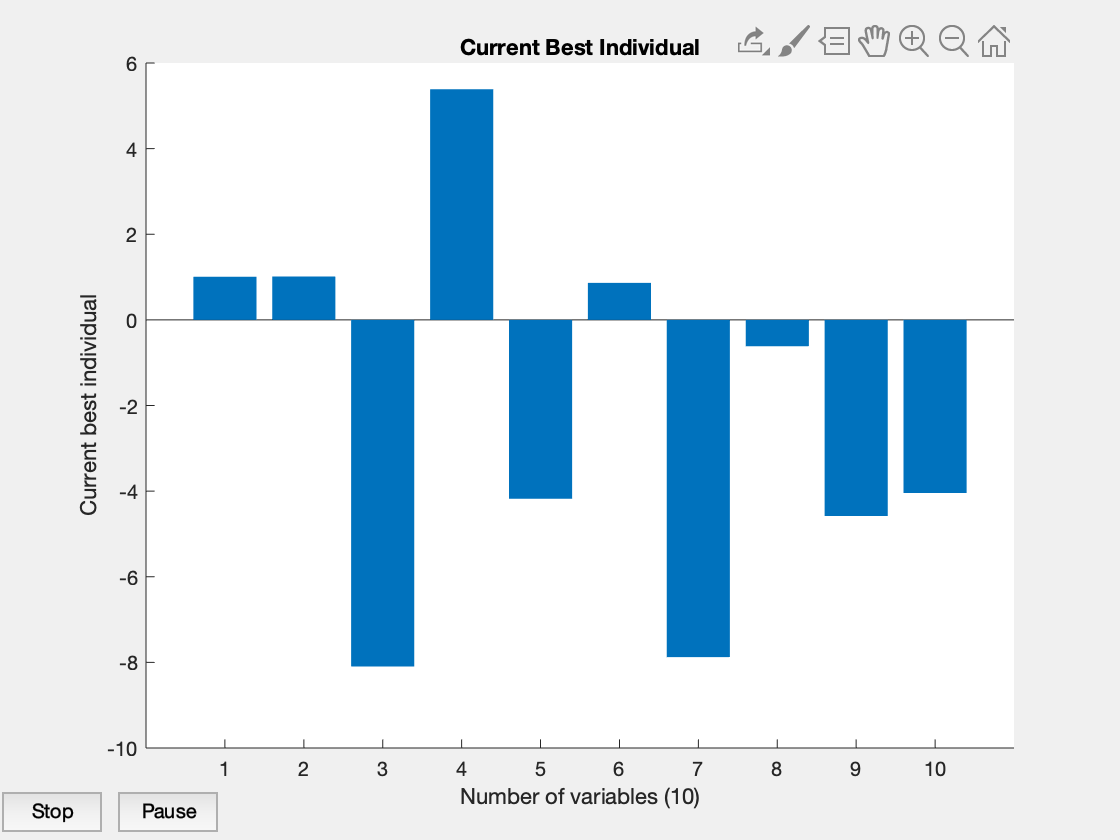

Optimization terminated: average change in the fitness value less than options.FunctionTolerance.


nvars=10;
lb = [0,0];
ub = [3,3];
popsize=100;

option = optimoptions('ga');
%option = optimoptions(option, 'PopulationType',"bitstring");
initial = optimoptions(option, 'InitialPopulationMatrix', popsize);

option1 = optimoptions(option,'PlotFcn','gaplotbestindiv');
option2 = optimoptions(option,'PlotFcn',{@gaplotbestf,@gaplotchange});

vectorizedoption = optimoptions(option,'UseVectorized',true);

rng(100)

[xvec1,fvalvec1,exitflagvec1,outputvec1,populationvec1,scorevec1] = ga(@(x) vectorized_fitness(x,100,1),nvars,[],[],[],[],lb,ub,[],option1);

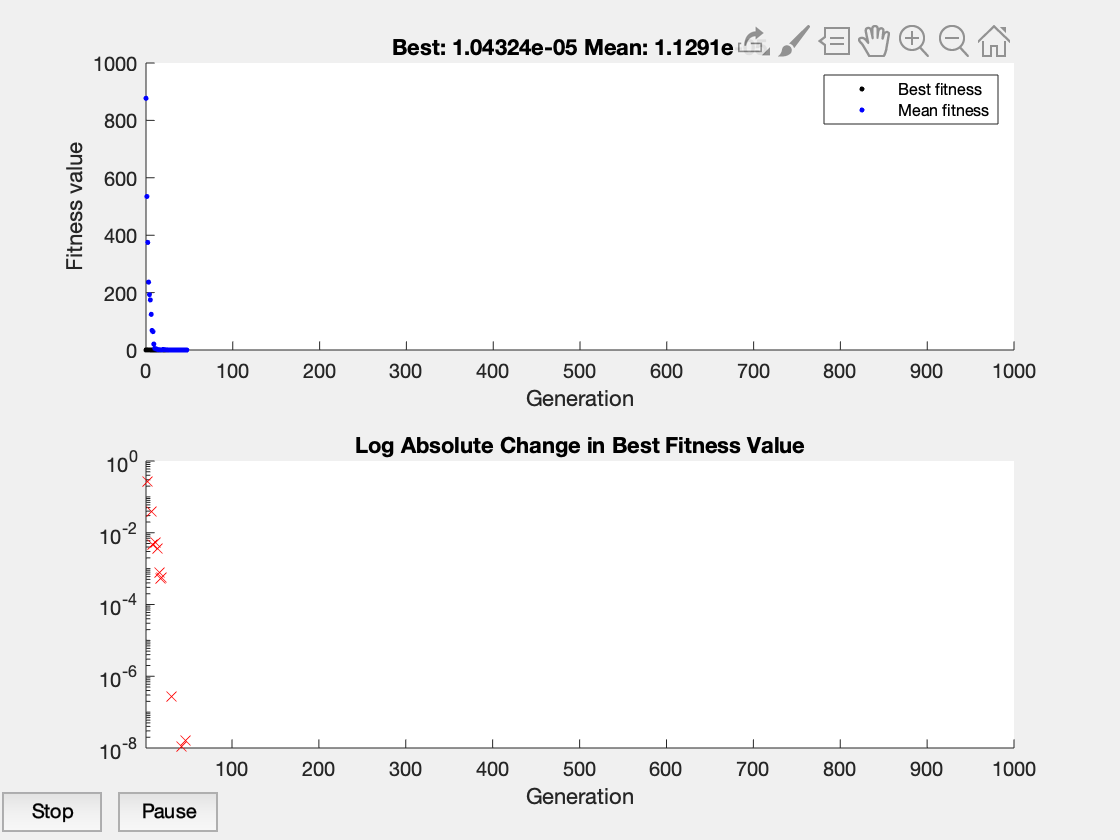

Optimization terminated: stop requested from plot function.


[xvec2,fvalvec2,exitflagvec2,outputvec2,populationvec2,scorevec2] = ga(@(x) vectorized_fitness(x,100,1),nvars,[],[],[],[],lb,ub,[],option2);


[xsimp1,fvalsimp1,exitflagsimp1,outputsimp1,populationsimp1,scoresimp1] = ga(@simple_fitness,nvars,[],[],[],[],lb,ub,[],option1);
[xsimp2,fvalsimp2,exitflagsimp2,outputsimp2,populationsimp2,scoresimp2] = ga(@simple_fitness,nvars,[],[],[],[],lb,ub,[],option2);



we can see the .... 

nParents = 10;
popusize = 10;
optiontravel = optimoptions('ga');
initialtravel = optimoptions(optiontravel, 'InitialPopulationMatrix', popusize);
scalingfitness = optimoptions(optiontravel,'FitnessScalingFcn',{@fitscalingtop,popusize});

%option11 = optimoptions(scalingfitness,'PlotFcn','gaplotbestindiv');
%option21 = optimoptions(scalingfitness,'PlotFcn',{@gaplotbestf,@gaplotchange});

%[xvec11,fvalvec11,exitflagvec11,outputvec11,populationvec11,scorevec11] = ga(@(x) vectorized_fitness(x,100,1),nvars,[],[],[],[],lb,ub,[],option11);
%[xvec21,fvalvec21,exitflagvec21,outputvec21,populationvec21,scorevec21] = ga(@(x) vectorized_fitness(x,100,1),nvars,[],[],[],[],lb,ub,[],option21);


option11 = optimoptions(optiontravel,'SelectionFcn',{@selectiontournament,popusize})

option11 =   ga options:

   Set properties:
                    SelectionFcn: {@selectiontournament  [10]}

   Default properties:
             ConstraintTolerance: 1.0000e-03
                     CreationFcn: @gacreationuniform
                    CrossoverFcn: @crossoverscattered
               CrossoverFraction: 0.8000
                         Display: 'final'
                      EliteCount: '0.05*PopulationSize'
                    FitnessLimit: -Inf
               FitnessScalingFcn: @fitscalingrank
               FunctionTolerance: 1.0000e-06
                       HybridFcn: []
         InitialPopulationMatrix: []
          InitialPopulationRange: []
             InitialScoresMatrix: []
                  MaxGenerations: '100*numberOfVariables'
             MaxStallGenerations: 50
                    MaxStallTime: Inf
                         MaxTime: Inf
                     MutationF

%option21 = optimoptions(optiontravel,'SelectionFcn')

%parents = optimoptions(optiontravel, nParents, @fitnessfun)

ok if we have teh first and last be the same then. .. . .. . 